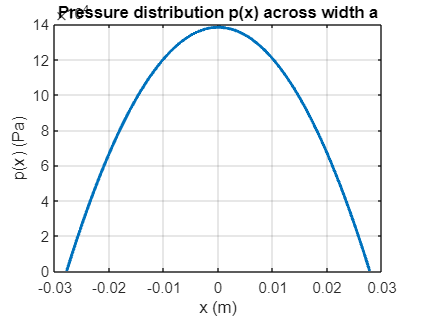

% https://mydailyengineering.wordpress.com/dry-steering/
% bilder av cad ligger i https://drive.google.com/drive/u/1/folders/1R42UJ85xGUDm-tD5RUjfcWQPFO0rt5rP
clc; clear; close all;

a_mm = 55.67; % mm kort side kontaktflate
b_mm = 154; % mm Langside kontaktflate
Fz_kg = 80.575; % kg vekt på hjulet
sigma_deg = 7.98; % deg KPI
tau_deg = 6.18; % deg caster
r_dyn_mm = 203.2; % mm radius hjul hjul
CD_mm = 28.48; % mm   r_dyn * tan sigma
rs_mm = 10.05; % mm  skrubb radie, DO linja
delta_deg = linspace(-30, 30, 1000);   % deg styrevinkel ÆÆÆÆÆÆÆ DE E FEIL


g = 9.81;         % m/s^2
a = a_mm*1e-3;    % m  
b = b_mm*1e-3;    % m
Fz = Fz_kg*g;      % N
x = linspace(-a/2, a/2, 1000);   % m
sigma = deg2rad(sigma_deg); % rad
tau = deg2rad(tau_deg); % rad
r_dyn = r_dyn_mm*1e-3; % m
CD = CD_mm*1e-3; % m
rs = rs_mm*1e-3; % m
delta = deg2rad(delta_deg); % rad


p = (6*Fz/(a^3*b)) .* (a/2 - x) .* (a/2 + x);  % Pa (N/m^2)


plot(x, p, 'LineWidth', 2)
grid on
xlabel('x (m)')
ylabel('p(x) (Pa)')
title('Pressure distribution p(x) across width a')

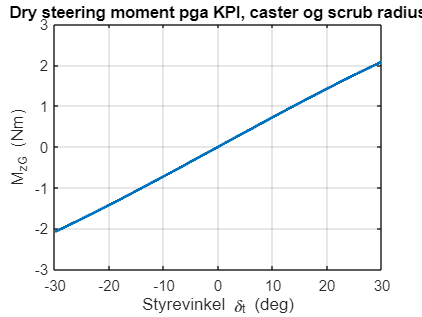


MzG = Fz * (rs + r_dyn*tan(sigma)) .* cos(sigma) .* sin(sigma) .* cos(tau) .* sin(delta); % Nm

figure
plot(delta_deg, MzG, 'LineWidth', 2)
grid on
xlabel('Styrevinkel \delta_t (deg)')
ylabel('M_{zG} (Nm)')
title('Dry steering moment pga KPI, caster og scrub radius')